# One versus all

This question uses a subset of the iris data - only the sepal widths and sepal lengths for all three classes:

clear all;
load('multiclass.mat', 'examples', 'labels');

This question is about training and visualising a set of Support Vector Machines (SVMs) in a one versus all (OVA) configuration in order to solve a multiclass problem. You should use the whole dataset (without splitting) for training. Note that the dataset has already been z-score stadardised.

Rather than using Matlab's built-in `fitcecoc()` function, your should develop your own function for training training binary SVMs in an OVA configuration (see the `myova_fit()` stub, below). You should then add your own functions to use the resulting model for prediction (see the `myova_predict()` stub, below) and for visualisation (see the `visualiseSVMs()` stub, below). You can base your work on the example shown here: [https://www.mathworks.com/help/stats/fitcsvm.html#bt9ce5p-1](https://www.mathworks.com/help/stats/fitcsvm.html#bt9ce5p-1) 

Marks are available for:

- Extending the `myova_fit()` function to train a set of SVMs in an OVA configuration using the `examples` and `labels` that are passed in [4 marks]

- Extending the `myova_predict()` function to classify new `test_examples` using any model, `m`, trained by the `myova_fit()` function [4 marks]

- Extending the `visualiseSVMs()` function to give a helpful visualisation of any 2D model, `m`, trained by the `myova_fit()` function (the visualisation should at least include the decision boundaries and the original training data) [8 marks]

- Convincing yourself the three functions work as you expect by using the data provided to reproduce at least one of the OVA visualisations from the lecture slides [4 marks]

[Total: 20 marks]

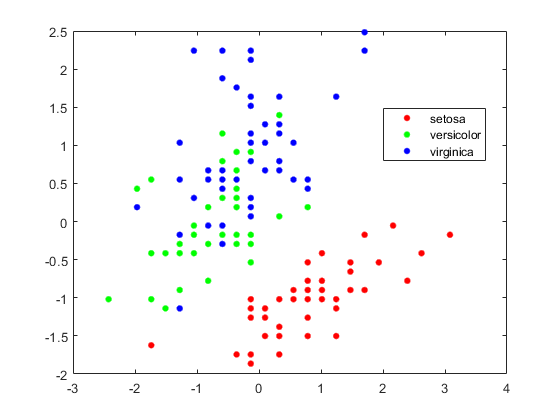

% add as many lines of code as you need below:

examples;
labels;

gscatter(examples{:,1},examples{:,2},labels)

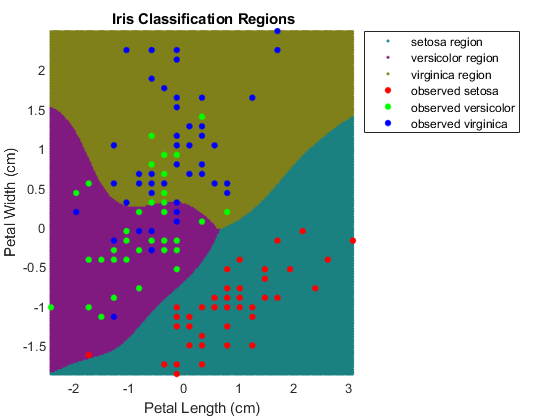

m = struct with fields:
    X: [150×2 double]
    Y: [150×1 categorical]



m = myova_fit(examples, labels)


%visualiseSVMs(m, examples, labels)

function m = myova_fit(examples, labels)

    % Hint 1: if you plan to directly re-work the code from the link 
    % above, then storing the original training examples/labels inside
    % the model, in variables called X and Y, will help make the job 
    % a bit easier:
    m.X = examples{:,:};
    m.Y = labels;
    % Hint 2: note that our 'labels' variable is a categorical array
    % (as usual). So you can't compare against the values it holds 
    % using strcmp(), as in the example code, but you can use logical 
    % operators like ==

    % Add as many lines of code as you need below:
    
    SVMModels = cell(3,1);
    classes = unique(m.Y);
    rng(1); % For reproducibility

    for j = 1:numel(classes)
        indx = (m.Y == classes(j)); % Create binary classes for each classifier
        SVMModels{j} = fitcsvm(m.X,indx,'ClassNames',[false true],'Standardize',true,'KernelFunction','rbf','BoxConstraint',1);
    end
    
    d = 0.02;
    [x1Grid,x2Grid] = meshgrid(min(m.X(:,1)):d:max(m.X(:,1)),...
    min(m.X(:,2)):d:max(m.X(:,2)));
    xGrid = [x1Grid(:),x2Grid(:)];
    N = size(xGrid,1);
    Scores = zeros(N,numel(classes));
    
    for j = 1:numel(classes)
        [~,score] = predict(SVMModels{j},xGrid);
        Scores(:,j) = score(:,2); % Second column contains positive-class scores
    end
    
    [~,maxScore] = max(Scores,[],2);
    
    figure
    h(1:3) = gscatter(xGrid(:,1),xGrid(:,2),maxScore,...
        [0.1 0.5 0.5; 0.5 0.1 0.5; 0.5 0.5 0.1]);
    hold on
    h(4:6) = gscatter(m.X(:,1),m.X(:,2),m.Y);
    title('{\bf Iris Classification Regions}');
    xlabel('Petal Length (cm)');
    ylabel('Petal Width (cm)');
    legend(h,{'setosa region','versicolor region','virginica region',...
        'observed setosa','observed versicolor','observed virginica'},...
        'Location','bestoutside');
    axis tight
    hold off
end

function predictions = myova_predict(m, test_examples)

    for j = 1:numel(classes)
        [~,score] = predict(SVMModels{j},xGrid);
        Scores(:,j) = score(:,2); % Second column contains positive-class scores
    end
    
    [~,maxScore] = max(Scores,[],2);
    
    figure
    h(1:3) = gscatter(xGrid(:,1),xGrid(:,2),maxScore,...
        [0.1 0.5 0.5; 0.5 0.1 0.5; 0.5 0.5 0.1]);
    hold on
    h(4:6) = gscatter(X(:,1),X(:,2),Y);
    title('{\bf Iris Classification Regions}');
    xlabel('Petal Length (cm)');
    ylabel('Petal Width (cm)');
    legend(h,{'setosa region','versicolor region','virginica region',...
        'observed setosa','observed versicolor','observed virginica'},...
        'Location','Northwest');
    axis tight
    hold off
end

function visualiseSVMs(m, examples, labels)

    hold on
    
    % find the min and the max of both columns in example data
    min1 = min(examples{:,1});
    max1 = max(examples{:,1});
    min2 = min(examples{:,2});
    max2 = max(examples{:,2});
    
    
    % create an array to hold the grid of visualisation points
    generatedExamples = [];
    
    % create nested for loop to loop from the min and the max of each column
    for i=min1:0.05:max1
        for j=min2:0.05:max2
            % add each value in the grid to the array
            generatedExamples = [generatedExamples; [i j]];
        end
    end
    
    % predict the outcome of each set of values in the grid
    gridpredictions = myova_predict(m, generatedExamples);
    % plot the points and their corresponding predictions
    gscatter(generatedExamples(:,1),generatedExamples(:,2),gridpredictions, 'rgb')
    
    % plot the original datapoints to visualize the classifiers accuracy:
    gscatter(examples{:,1},examples{:,2},labels, 'kmb')
    % add x and y labels and a legend to ensure clarity:
    xlabel("Sepal Width")
    ylabel("Sepal Length")
    title("Iris data SVM onevsone")
    legend('Setosa Test','Versicolor Test', 'Virginica Test', 'Setosa','Versicolour', 'Virginica', 'Location', "bestoutside");
 
    hold off
    

end